# Machine Learning: Programming Exercise 3

## Multi-class Classification and Neural Networks

In this exercise, you will implement one-vs-all logistic regression and neural networks to recognize hand-written digits.

### Files needed for this exercise

- `ex3.mlx` - MATLAB Live Script that steps you through the exercise

- `ex3data1.mat` - Training set of hand-written digits

- `ex3weights.mat` - Initial weights for the neural network exercise

- `submit.m `- Submission script that sends your solutions to our servers

- `displayData.m` - Function to help visualize the dataset

- `fmincg.m` - Function minimization routine (similar to `fminunc`)

- `sigmoid.m` - Sigmoid function

- `*lrCostFunction.m` - Logistic regression cost function

- `*oneVsAll.m` - Train a one-vs-all multi-class classifier

- `*predictOneVsAll.m` - Predict using a one-vs-all multi-class classifier

- `*predict.m `- Neural network prediction function

****indicates files you will need to complete***

#### Confirm that your Current Folder is set correctly

Click into this section, then click the 'Run section' button above. This will execute the `dir` command below to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex3' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

dir


.                  displayData.m      ex3_companion.mat  ex3data1.mat       fmincg.m           lrCostFunction.m   predict.m          sigmoid.m          token.mat          
..                 ex3.mlx            ex3_companion.mlx  ex3weights.mat     lib                oneVsAll.m         predictOneVsAll.m  submit.m           



### Before you begin

The workflow for completing and submitting the programming exercises in MATLAB Online differs from the original course instructions. Before beginning this exercise, make sure you have read through the instructions in `README.mlx` which is included with the programming exercise files. `README` also contains solutions to the many common issues you may encounter while completing and submitting the exercises in MATLAB Online. Make sure you are following instructions in `README` and have checked for an existing solution before seeking help on the discussion forums.

## 1. Multi-class Classification

For this exercise, you will use logistic regression and neural networks to recognize handwritten digits (from 0 to 9). Automated handwritten digit recognition is widely used today - from recognizing zip codes (postal codes) on mail envelopes to recognizing amounts written on bank checks. This exercise will show you how the methods you've learned can be used for this classication task. In the first part of the exercise, you will extend your previous implemention of logistic regression and apply it to one-vs-all classification.

### 1.1 Dataset

You are given a data set in `ex3data1.mat` that contains 5000 training examples of handwritten digits*. The .mat format means that that the data has been saved in a native MATLAB matrix format, instead of a text (ASCII) format like a csv-file. These matrices can be read directly into your program by using the load command. After loading, matrices of the correct dimensions and values will appear in your program's memory. The matrix will already be named, so you do not need to assign names to them. 

**This is a subset of the MNIST *[*handwritten digit dataset*](http://yann.lecun.com/exdb/mnist/))

Run the code below to load the data.

% Load saved matrices from file
load('ex3data1.mat');
% The matrices X and y will now be in your MATLAB environment

    There are 5000 training examples in `ex3data1.mat`, where each training example is a 20 pixel by 20 pixel grayscale image of the digit. Each pixel is represented by a floating point number indicating the grayscale intensity at that location. The 20 by 20 grid of pixels is 'unrolled' into a 400-dimensional vector. Each of these training examples becomes a single row in our data matrix `X`. This gives us a 5000 by 400 matrix `X` where every row is a training example for a handwritten digit image.


$$X=\left\lbrack \begin{array}{c}
-{\left(x^{\left(1\right)} \right)}^T -\\
-{\left(x^{\left(2\right)} \right)}^T -\\
\vdots \\
-{\left(x^{\left(m\right)} \right)}^T -
\end{array}\right\rbrack$$


    The second part of the training set is a 5000-dimensional vector `y` that contains labels for the training set. To make things more compatible with MATLAB indexing, where there is no zero index, we have mapped the digit zero to the value ten. Therefore, a '0' digit is labeled as '10', while the digits '1' to '9' are labeled as '1' to '9' in their natural order.

## 1.2 Visualizing the data

You will begin by visualizing a subset of the training set. The code below randomly selects selects 100 rows from `X` and passes those rows to the `displayData` function. This function maps each row to a 20 pixel by 20 pixel grayscale image and displays the images together. We have provided the `displayData` function, and you are encouraged to examine the code to see how it works. After you run this step, you should see an image like Figure 1.

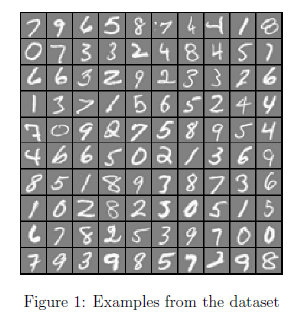                        

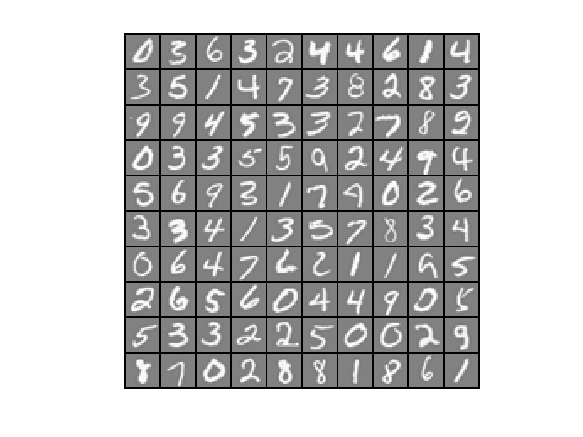

m = size(X, 1);
% Randomly select 100 data points to display
rand_indices = randperm(m);
sel = X(rand_indices(1:100), :);

displayData(sel);

### 1.3 Vectorizing logistic regression

You will be using multiple one-vs-all logistic regression models to build a multi-class classifier. Since there are 10 classes, you will need to train 10 separate logistic regression classifiers. To make this training efficient, it is important to ensure that your code is well vectorized. In this section, you will implement a vectorized version of logistic regression that does not employ any `for` loops. You can use your code in the last exercise as a starting point for this exercise.

#### 1.3.1 Vectorizing the cost function

We will begin by writing a vectorized version of the cost function. Recall that in (unregularized) logistic regression, the cost function is


$$J(\theta) =\frac{1}{m}\sum_{i=1}^m{\left[

-y^{(i)} \log(h_{\theta}(x^{(i)}))- (1-y^{(i)}) \log(1- h_{\theta}(x^{(i)}))\right],$$


To compute each element in the summation, we have to compute $h_{\theta}(x^{(i)})$ for every example $i$, where $h_{\theta}(x^{(i)}) = g(\theta^T x^{(i)})$ and $g(z) =\frac{1}{1+e^{-z}}$ is the sigmoid function. It turns out that we can compute this quickly for all our examples by using matrix multiplication. Let us define $X$ and $\theta$ as


$$X\theta \text{ }=\left\lbrack \begin{array}{c}
-{\left(x^{\left(1\right)} \right)}^T \theta \text{ }-\\
-{\left(x^{\left(2\right)} \right)}^T \theta \text{ }-\\
\vdots \\
-{\left(x^{\left(m\right)} \right)}^T \theta \text{ }-
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-\text{ }\theta^T \left(x^{\left(1\right)} \right)-\\
-{\text{ }\theta }^T \left(x^{\left(2\right)} \right)\text{ }-\\
\vdots \\
-{\text{ }\theta }^T \left(x^{\left(m\right)} \right)-
\end{array}\right\rbrack \text{ }$$


In the last equality, we used the fact that $a^T b= b^T a$ if $a$ and $b$ are vectors. This allows us to compute the products $\theta^T x^{(i)}$ for all our examples $i$ in one line of code.

    Your job is to write the unregularized cost function in the file `lrCostFunction.m `Your implementation should use the strategy we presented above to calculate $\theta^T x^{(i)}$. You should also use a vectorized approach for the rest of the cost function. A fully vectorized version of `lrCostFunction.m` should not contain any loops. (Hint: You might want to use the element-wise multiplication operation (`.*`) and the sum operation `sum` when writing this function)

#### 1.3.2 Vectorizing the gradient

Recall that the gradient of the (unregularized) logistic regression cost is a vector where the $j$th element is defined as 


$$\frac{\partial J(\theta)}{\partial \theta_j} = \frac{1}{m}\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_j^{(i)}
$$


To vectorize this operation over the dataset, we start by writing out all the partial derivatives explicitly for all $\theta_j$,

$\left[ \begin{array}{c} 
\frac{\partial J(\theta)}{\partial \theta_0} \\
\frac{\partial J(\theta)}{\partial \theta_1} \\
\frac{\partial J(\theta)}{\partial \theta_2} \\
\vdots \\
\frac{\partial J(\theta)}{\partial \theta_n}   
 \end{array} \right]
 = \frac{1}{m}
\left[ \begin{array}{c} 
\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_0^{(i)} \\
\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_1^{(i)} \\
\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_2^{(i)} \\
\vdots \\
\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_n^{(i)}
\end{array}\right] =\frac{1}{m} \sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x^{(i)} =
\frac{1}{m}X^T {\left( h_\theta(x)-y\right)}
$   (1)

where


$$h_{\theta \text{ }} \left(x\right)-y=\left\lbrack \begin{array}{c}
h_{\theta \text{ }} \left(x^{\left(1\right)} \right)-y^{\left(1\right)} \\
h_{\theta \text{ }} \left(x^{\left(2\right)} \right)-y^{\left(2\right)} \\
\vdots \\
h_{\theta \text{ }} \left(x^{\left(m\right)} \right)-y^{\left(m\right)} 
\end{array}\right\rbrack$$


    Note that $x^{(i)}$ is a vector, while $(h_\theta(x^{(i)})-y^{(i)})$ is a scalar (single number). To understand the last step of the derivation, let $\beta_i = (h_\theta(x^{(i)})-y^{(i)})$ and observe that:


$$\sum_{i} \beta_i x^{\left(i\right)} =\left\lbrack \begin{array}{cccc}
| & | & \text{ } & |\\
x^{\left(1\right)}  & x^{\left(2\right)}  & \dots  & x^{\left(m\right)} \\
| & | & \text{ } & |
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\beta_1 \\
\beta_2 \\
\vdots \\
\beta_m 
\end{array}\right\rbrack =X^T \beta ,$$


    The expression above allows us to compute all the partial derivatives without any loops. If you are comfortable with linear algebra, we encourage you to work through the matrix multiplications above to convince yourself that the vectorized version does the same computations. You should now implement Equation (1) to compute the correct vectorized gradient. Once you are done, complete the function `lrCostFunction.m` by implementing the gradient.

**Debugging Tip: **Vectorizing code can sometimes be tricky. One common strategy for debugging is to print out the sizes of the matrices you are working with using the size function. For example, given a data matrix $X$ of size 100 x 20 (100 examples, 20 features) and $\theta$, a vector with dimensions 20 x 1, you can observe that $X\theta$ is a valid multiplication operation, while $\theta X$ is not. Furthermore, if you have a non-vectorized version of your code, you can compare the output of your vectorized code and non-vectorized code to make sure that they produce the same outputs.

#### 1.3.3 Vectorizing regularized logistic regression

After you have implemented vectorization for logistic regression, you will now add regularization to the cost function. Recall that for regularized logistic regression, the cost function is defined as


$$J(\theta) =\frac{1}{m}\sum_{i=1}^m{\left[

-y^{(i)} \log(h_{\theta}(x^{(i)}))- (1 -y^{(i)}) \log(1-h_{\theta}(x^{(i)}))\right]+\frac{\lambda}{2m}\sum_{j=1}^n{\theta_j^2}$$


Note that you should not be regularizing $\theta_0$ which is used for the bias term. Correspondingly, the partial derivative of regularized logistic regression cost for $\theta_j$ is defined as


$$\frac{\partial J(\theta)}{\partial \theta_j} = \frac{1}{m}\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_j^{(i)}\qquad \mathrm{for}\;j=0,
$$



$$\frac{\partial J(\theta)}{\partial \theta_j} = \left( \frac{1}{m}\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_j^{(i)}} \right)+\frac{\lambda}{m}\theta_j\qquad \mathrm{for}\;j\geq1$$


Now modify your code in `lrCostFunction` to account for regularization. Once again, you should not put any loops into your code. When you are finished, run the code below to test your vectorized implementation and compare to expected outputs:

theta_t = [-2; -1; 1; 2];
X_t = [ones(5,1) reshape(1:15,5,3)/10];
y_t = ([1;0;1;0;1] >= 0.5);
lambda_t = 3;
[J, grad] = lrCostFunction(theta_t, X_t, y_t, lambda_t);

ans =      5     4


ans =      4     1



fprintf('Cost: %f | Expected cost: 2.534819\n',J);

Cost: 2.534819 | Expected cost: 2.534819


fprintf('Gradients:\n'); fprintf('%f\n',grad);

Gradients:
0.146561
-0.548558
0.724722
1.398003


fprintf('Expected gradients:\n 0.146561\n -0.548558\n 0.724722\n 1.398003');

Expected gradients:
 0.146561
 -0.548558
 0.724722
 1.398003

**MATLAB Tip:** When implementing the vectorization for regularized logistic regression, you might often want to only sum and update certain elements of $\theta$. In MATLAB, you can index into the matrices to access and update only certain elements. For example, `A(:,3:5)= B(:, 1:3)` will replace columns 3 to 5 of `A` with the columns 1 to 3 from `B`. One special keyword you can use in indexing is the `end` keyword in indexing. This allows us to select columns (or rows) until the end of the matrix. For example, `A(:, 2:end)` will only return elements from the 2nd to last column of `A`. Thus, you could use this together with the `sum` and `.^` operations to compute the sum of only the elements you are interested in (e.g. `sum(z(2:end).^2))`. In the starter code,` lrCostFunction.m`, we have also provided hints on yet another possible method computing the regularized gradient.

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 1.4 One-vs-all classication

In this part of the exercise, you will implement one-vs-all classification by training multiple regularized logistic regression classifiers, one for each of the $K$ classes in our dataset (Figure 1). In the handwritten digits dataset, $K = 10$, but your code should work for any value of $K$. 

    You should now complete the code in `oneVsAll.m` to train one classifier for each class. In particular, your code should return all the classifier parameters in a matrix $\Theta \in \mathbb{R}^{K\times(N+1)}$, where each row of $\Theta$ corresponds to the learned logistic regression parameters for one class. You can do this with a `for` loop from 1 to `K`, training each classifier independently.

Note that the `y` argument to this function is a vector of labels from 1 to 10, where we have mapped the digit '0' to the label 10 (to avoid confusions with indexing). When training the classifier for class $k \in \{1,\ldots,K\},$ you will want a $m$-dimensional vector of labels $y,$ where $y_j\in \{0,\;1\}$ indicates whether the $j$-th training instance belongs to class $k\; (y_j = 1)$, or if it belongs to a different class $(y_j = 0).$ You may find logical arrays helpful for this task.

**MATLAB Tip**: Logical arrays in MATLAB are arrays which contain binary (0 or 1) elements. In MATLAB, evaluating the expression `a == b` for a vector `a` (of size $m\times1$) and scalar `b` will return a vector of the same size as `a` with ones at positions where the elements of `a` are equal to `b` and zeroes where they are different. To see how this works for yourself, run the following code:

a = 1:10; % Create a and b
b = 3;
disp(a == b) % You should try different values of b here

   0   0   1   0   0   0   0   0   0   0



Furthermore, you will be using `fmincg` for this exercise (instead of `fminunc`). `fmincg` works similarly to `fminunc`, but is more more efficient for dealing with a large number of parameters. After you have correctly completed the code for `oneVsAll.m`, run the code below to use your `oneVsAll` function to train a multi-class classifier.

num_labels = 10; % 10 labels, from 1 to 10 
lambda = 0.1;
[all_theta] = oneVsAll(X, y, num_labels, lambda);

ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration     1 | Cost: 2.802128e-01


ans =         5000         401


ans =    401     1


Iteration     2 | Cost: 9.454389e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration     3 | Cost: 5.704641e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration     4 | Cost: 4.688190e-02


ans =         5000         401


ans =    401     1


Iteration     5 | Cost: 3.759021e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration     6 | Cost: 3.522008e-02


ans =         5000         401


ans =    401     1


Iteration     7 | Cost: 3.234531e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration     8 | Cost: 3.145034e-02


ans =         5000         401


ans =    401     1


Iteration     9 | Cost: 3.008919e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    10 | Cost: 2.994639e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    11 | Cost: 2.678528e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    12 | Cost: 2.660323e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    13 | Cost: 2.493301e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    14 | Cost: 2.475211e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    15 | Cost: 2.318421e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    16 | Cost: 2.287050e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    17 | Cost: 2.160258e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    18 | Cost: 2.120371e-02


ans =         5000         401


ans =    401     1


Iteration    19 | Cost: 2.064125e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    20 | Cost: 2.055695e-02


ans =         5000         401


ans =    401     1


Iteration    21 | Cost: 2.045466e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    22 | Cost: 2.029177e-02


ans =         5000         401


ans =    401     1


Iteration    23 | Cost: 2.005296e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    24 | Cost: 1.995949e-02


ans =         5000         401


ans =    401     1


Iteration    25 | Cost: 1.982849e-02


ans =         5000         401


ans =    401     1


Iteration    26 | Cost: 1.975129e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    27 | Cost: 1.897815e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    28 | Cost: 1.887065e-02


ans =         5000         401


ans =    401     1


Iteration    29 | Cost: 1.869107e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    30 | Cost: 1.863223e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    31 | Cost: 1.837394e-02


ans =         5000         401


ans =    401     1


Iteration    32 | Cost: 1.816951e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    33 | Cost: 1.781689e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    34 | Cost: 1.774665e-02


ans =         5000         401


ans =    401     1


Iteration    35 | Cost: 1.767439e-02


ans =         5000         401


ans =    401     1


Iteration    36 | Cost: 1.758469e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    37 | Cost: 1.756839e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    38 | Cost: 1.753325e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    39 | Cost: 1.727845e-02


ans =         5000         401


ans =    401     1


Iteration    40 | Cost: 1.701775e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    41 | Cost: 1.621756e-02


ans =         5000         401


ans =    401     1


Iteration    42 | Cost: 1.532258e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    43 | Cost: 1.489725e-02


ans =         5000         401


ans =    401     1


Iteration    44 | Cost: 1.449840e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    45 | Cost: 1.440343e-02


ans =         5000         401


ans =    401     1


Iteration    46 | Cost: 1.426266e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    47 | Cost: 1.424738e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    48 | Cost: 1.412823e-02


ans =         5000         401


ans =    401     1


Iteration    49 | Cost: 1.404076e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    50 | Cost: 1.399680e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration     1 | Cost: 3.448901e-01


ans =         5000         401


ans =    401     1


Iteration     2 | Cost: 3.150694e-01


ans =         5000         401


ans =    401     1


Iteration     3 | Cost: 1.846843e-01


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration     4 | Cost: 1.699017e-01


ans =         5000         401


ans =    401     1


Iteration     5 | Cost: 1.529566e-01


ans =         5000         401


ans =    401     1


Iteration     6 | Cost: 1.317377e-01


ans =         5000         401


ans =    401     1


Iteration     7 | Cost: 1.171533e-01


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration     8 | Cost: 1.074286e-01


ans =         5000         401


ans =    401     1


Iteration     9 | Cost: 9.531806e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    10 | Cost: 9.301912e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    11 | Cost: 8.418356e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    12 | Cost: 8.186322e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    13 | Cost: 7.743126e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    14 | Cost: 7.645181e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    15 | Cost: 7.209877e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    16 | Cost: 7.195896e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    17 | Cost: 7.106302e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    18 | Cost: 7.081516e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    19 | Cost: 6.984782e-02


ans =         5000         401


ans =    401     1


Iteration    20 | Cost: 6.908892e-02


ans =         5000         401


ans =    401     1


Iteration    21 | Cost: 6.818820e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    22 | Cost: 6.804182e-02


ans =         5000         401


ans =    401     1


Iteration    23 | Cost: 6.788125e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    24 | Cost: 6.779397e-02


ans =         5000         401


ans =    401     1


Iteration    25 | Cost: 6.767277e-02


ans =         5000         401


ans =    401     1


Iteration    26 | Cost: 6.760372e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    27 | Cost: 6.740638e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    28 | Cost: 6.731728e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    29 | Cost: 6.698888e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    30 | Cost: 6.692984e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    31 | Cost: 6.630404e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    32 | Cost: 6.606809e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    33 | Cost: 6.466816e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    34 | Cost: 6.426962e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    35 | Cost: 6.267791e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    36 | Cost: 6.251576e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    37 | Cost: 6.202834e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    38 | Cost: 6.188521e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    39 | Cost: 6.013896e-02


ans =         5000         401


ans =    401     1


Iteration    40 | Cost: 5.937078e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    41 | Cost: 5.888593e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    42 | Cost: 5.862828e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    43 | Cost: 5.854428e-02


ans =         5000         401


ans =    401     1


Iteration    44 | Cost: 5.847598e-02


ans =         5000         401


ans =    401     1


Iteration    45 | Cost: 5.840091e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    46 | Cost: 5.812347e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    47 | Cost: 5.803255e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    48 | Cost: 5.773508e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    49 | Cost: 5.763068e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    50 | Cost: 5.725244e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration     1 | Cost: 3.456557e-01


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration     2 | Cost: 2.179164e-01


ans =         5000         401


ans =    401     1


Iteration     3 | Cost: 1.784174e-01


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration     4 | Cost: 1.678808e-01


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration     5 | Cost: 1.427129e-01


ans =         5000         401


ans =    401     1


Iteration     6 | Cost: 1.150393e-01


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration     7 | Cost: 1.063718e-01


ans =         5000         401


ans =    401     1


Iteration     8 | Cost: 9.707803e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration     9 | Cost: 9.518367e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    10 | Cost: 9.035733e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    11 | Cost: 8.928846e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    12 | Cost: 8.531186e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    13 | Cost: 8.333526e-02


ans =         5000         401


ans =    401     1


Iteration    14 | Cost: 8.052683e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    15 | Cost: 7.932857e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    16 | Cost: 7.672637e-02


ans =         5000         401


ans =    401     1


Iteration    17 | Cost: 7.530942e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    18 | Cost: 7.500108e-02


ans =         5000         401


ans =    401     1


Iteration    19 | Cost: 7.445295e-02


ans =         5000         401


ans =    401     1


Iteration    20 | Cost: 7.391453e-02


ans =         5000         401


ans =    401     1


Iteration    21 | Cost: 7.349869e-02


ans =         5000         401


ans =    401     1


Iteration    22 | Cost: 7.307295e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    23 | Cost: 7.296937e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    24 | Cost: 7.262398e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    25 | Cost: 7.129794e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    26 | Cost: 7.118480e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    27 | Cost: 7.089717e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    28 | Cost: 6.963444e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    29 | Cost: 6.959800e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    30 | Cost: 6.916222e-02


ans =         5000         401


ans =    401     1


Iteration    31 | Cost: 6.893777e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    32 | Cost: 6.891916e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    33 | Cost: 6.872551e-02


ans =         5000         401


ans =    401     1


Iteration    34 | Cost: 6.853727e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    35 | Cost: 6.849807e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    36 | Cost: 6.754812e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    37 | Cost: 6.715238e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    38 | Cost: 6.581736e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    39 | Cost: 6.572985e-02


ans =         5000         401


ans =    401     1


Iteration    40 | Cost: 6.556018e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    41 | Cost: 6.516077e-02


ans =         5000         401


ans =    401     1


Iteration    42 | Cost: 6.465303e-02


ans =         5000         401


ans =    401     1


Iteration    43 | Cost: 6.445859e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    44 | Cost: 6.445323e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    45 | Cost: 6.438567e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    46 | Cost: 6.422333e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    47 | Cost: 6.421326e-02


ans =         5000         401


ans =    401     1


Iteration    48 | Cost: 6.420442e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    49 | Cost: 6.414200e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    50 | Cost: 6.413441e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration     1 | Cost: 3.205301e-01


ans =         5000         401


ans =    401     1


Iteration     2 | Cost: 3.040759e-01


ans =         5000         401


ans =    401     1


Iteration     3 | Cost: 1.649080e-01


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration     4 | Cost: 1.438784e-01


ans =         5000         401


ans =    401     1


Iteration     5 | Cost: 9.416994e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration     6 | Cost: 9.044270e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration     7 | Cost: 7.499076e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration     8 | Cost: 7.202465e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration     9 | Cost: 6.313221e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    10 | Cost: 6.168143e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    11 | Cost: 5.762801e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    12 | Cost: 5.638036e-02


ans =         5000         401


ans =    401     1


Iteration    13 | Cost: 5.517793e-02


ans =         5000         401


ans =    401     1


Iteration    14 | Cost: 5.405985e-02


ans =         5000         401


ans =    401     1


Iteration    15 | Cost: 5.332997e-02


ans =         5000         401


ans =    401     1


Iteration    16 | Cost: 5.177817e-02


ans =         5000         401


ans =    401     1


Iteration    17 | Cost: 5.019780e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    18 | Cost: 5.009061e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    19 | Cost: 4.933097e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    20 | Cost: 4.906466e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    21 | Cost: 4.795494e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    22 | Cost: 4.787525e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    23 | Cost: 4.736361e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    24 | Cost: 4.703862e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    25 | Cost: 4.594098e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    26 | Cost: 4.581044e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    27 | Cost: 4.439915e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    28 | Cost: 4.419360e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    29 | Cost: 4.354883e-02


ans =         5000         401


ans =    401     1


Iteration    30 | Cost: 4.267110e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    31 | Cost: 4.260380e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    32 | Cost: 4.239256e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    33 | Cost: 4.229373e-02


ans =         5000         401


ans =    401     1


Iteration    34 | Cost: 4.216016e-02


ans =         5000         401


ans =    401     1


Iteration    35 | Cost: 4.201368e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    36 | Cost: 4.197876e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    37 | Cost: 4.190686e-02


ans =         5000         401


ans =    401     1


Iteration    38 | Cost: 4.180323e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    39 | Cost: 4.176141e-02


ans =         5000         401


ans =    401     1


Iteration    40 | Cost: 4.172895e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    41 | Cost: 4.171275e-02


ans =         5000         401


ans =    401     1


Iteration    42 | Cost: 4.169614e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    43 | Cost: 4.163264e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    44 | Cost: 4.098750e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    45 | Cost: 4.084060e-02


ans =         5000         401


ans =    401     1


Iteration    46 | Cost: 4.067088e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    47 | Cost: 3.781016e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    48 | Cost: 3.676517e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    49 | Cost: 3.614011e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    50 | Cost: 3.597822e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration     1 | Cost: 3.314410e-01


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration     2 | Cost: 2.217377e-01


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration     3 | Cost: 1.929205e-01


ans =         5000         401


ans =    401     1


Iteration     4 | Cost: 1.568866e-01


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration     5 | Cost: 1.318005e-01


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration     6 | Cost: 1.147878e-01


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration     7 | Cost: 1.124131e-01


ans =         5000         401


ans =    401     1


Iteration     8 | Cost: 1.083564e-01


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration     9 | Cost: 1.069107e-01


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    10 | Cost: 1.022962e-01


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    11 | Cost: 1.017049e-01


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    12 | Cost: 9.879326e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    13 | Cost: 9.731696e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    14 | Cost: 9.216899e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    15 | Cost: 9.032623e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    16 | Cost: 8.409627e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    17 | Cost: 8.140204e-02


ans =         5000         401


ans =    401     1


Iteration    18 | Cost: 7.863906e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    19 | Cost: 7.835122e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    20 | Cost: 7.711350e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    21 | Cost: 7.671192e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    22 | Cost: 7.538515e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    23 | Cost: 7.517315e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    24 | Cost: 7.352966e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    25 | Cost: 7.269690e-02


ans =         5000         401


ans =    401     1


Iteration    26 | Cost: 7.167827e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    27 | Cost: 7.156798e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    28 | Cost: 7.107344e-02


ans =         5000         401


ans =    401     1


Iteration    29 | Cost: 7.057249e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    30 | Cost: 7.054742e-02


ans =         5000         401


ans =    401     1


Iteration    31 | Cost: 7.051131e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    32 | Cost: 7.027145e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    33 | Cost: 7.015020e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    34 | Cost: 6.963282e-02


ans =         5000         401


ans =    401     1


Iteration    35 | Cost: 6.921892e-02


ans =         5000         401


ans =    401     1


Iteration    36 | Cost: 6.867102e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    37 | Cost: 6.864035e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    38 | Cost: 6.838629e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    39 | Cost: 6.832040e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    40 | Cost: 6.803653e-02


ans =         5000         401


ans =    401     1


Iteration    41 | Cost: 6.775374e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    42 | Cost: 6.726305e-02


ans =         5000         401


ans =    401     1


Iteration    43 | Cost: 6.682683e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    44 | Cost: 6.473349e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    45 | Cost: 6.414682e-02


ans =         5000         401


ans =    401     1


Iteration    46 | Cost: 6.344954e-02


ans =         5000         401


ans =    401     1


Iteration    47 | Cost: 6.291565e-02


ans =         5000         401


ans =    401     1


Iteration    48 | Cost: 6.235622e-02


ans =         5000         401


ans =    401     1


Iteration    49 | Cost: 6.198288e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    50 | Cost: 6.187121e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration     1 | Cost: 3.354875e-01


ans =         5000         401


ans =    401     1


Iteration     2 | Cost: 2.188639e-01


ans =         5000         401


ans =    401     1


Iteration     3 | Cost: 9.772130e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration     4 | Cost: 8.460314e-02


ans =         5000         401


ans =    401     1


Iteration     5 | Cost: 5.991024e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration     6 | Cost: 5.318810e-02


ans =         5000         401


ans =    401     1


Iteration     7 | Cost: 4.521935e-02


ans =         5000         401


ans =    401     1


Iteration     8 | Cost: 4.117442e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration     9 | Cost: 3.978801e-02


ans =         5000         401


ans =    401     1


Iteration    10 | Cost: 3.874084e-02


ans =         5000         401


ans =    401     1


Iteration    11 | Cost: 3.814846e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    12 | Cost: 3.812015e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    13 | Cost: 3.791387e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    14 | Cost: 3.720946e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    15 | Cost: 3.578365e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    16 | Cost: 3.474696e-02


ans =         5000         401


ans =    401     1


Iteration    17 | Cost: 3.395842e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    18 | Cost: 3.351052e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    19 | Cost: 3.326145e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    20 | Cost: 3.314033e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    21 | Cost: 3.180976e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    22 | Cost: 3.138624e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    23 | Cost: 3.012590e-02


ans =         5000         401


ans =    401     1


Iteration    24 | Cost: 2.930241e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    25 | Cost: 2.893185e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    26 | Cost: 2.802474e-02


ans =         5000         401


ans =    401     1


Iteration    27 | Cost: 2.666012e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    28 | Cost: 2.654573e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    29 | Cost: 2.573053e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    30 | Cost: 2.537199e-02


ans =         5000         401


ans =    401     1


Iteration    31 | Cost: 2.517240e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    32 | Cost: 2.513433e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    33 | Cost: 2.503069e-02


ans =         5000         401


ans =    401     1


Iteration    34 | Cost: 2.494551e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    35 | Cost: 2.493218e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    36 | Cost: 2.480205e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    37 | Cost: 2.433131e-02


ans =         5000         401


ans =    401     1


Iteration    38 | Cost: 2.390593e-02


ans =         5000         401


ans =    401     1


Iteration    39 | Cost: 2.342369e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    40 | Cost: 2.341125e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    41 | Cost: 2.329112e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    42 | Cost: 2.282199e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    43 | Cost: 2.268687e-02


ans =         5000         401


ans =    401     1


Iteration    44 | Cost: 2.261398e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    45 | Cost: 2.261310e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    46 | Cost: 2.257884e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    47 | Cost: 2.247714e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    48 | Cost: 2.245859e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    49 | Cost: 2.237483e-02


ans =         5000         401


ans =    401     1


Iteration    50 | Cost: 2.231715e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration     1 | Cost: 3.142799e-01


ans =         5000         401


ans =    401     1


Iteration     2 | Cost: 1.938915e-01


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration     3 | Cost: 9.858322e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration     4 | Cost: 8.666461e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration     5 | Cost: 6.518233e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration     6 | Cost: 6.163782e-02


ans =         5000         401


ans =    401     1


Iteration     7 | Cost: 5.886007e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration     8 | Cost: 5.773973e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration     9 | Cost: 5.334455e-02


ans =         5000         401


ans =    401     1


Iteration    10 | Cost: 5.036396e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    11 | Cost: 4.994868e-02


ans =         5000         401


ans =    401     1


Iteration    12 | Cost: 4.964157e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    13 | Cost: 4.945483e-02


ans =         5000         401


ans =    401     1


Iteration    14 | Cost: 4.920530e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    15 | Cost: 4.880147e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    16 | Cost: 4.766125e-02


ans =         5000         401


ans =    401     1


Iteration    17 | Cost: 4.683578e-02


ans =         5000         401


ans =    401     1


Iteration    18 | Cost: 4.573370e-02


ans =         5000         401


ans =    401     1


Iteration    19 | Cost: 4.507942e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    20 | Cost: 4.501869e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    21 | Cost: 4.433528e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    22 | Cost: 4.271154e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    23 | Cost: 4.251498e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    24 | Cost: 4.191880e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    25 | Cost: 4.178635e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    26 | Cost: 4.147292e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    27 | Cost: 4.139877e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    28 | Cost: 4.119548e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    29 | Cost: 4.051790e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    30 | Cost: 4.039230e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    31 | Cost: 3.980256e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    32 | Cost: 3.956674e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    33 | Cost: 3.884204e-02


ans =         5000         401


ans =    401     1


Iteration    34 | Cost: 3.804687e-02


ans =         5000         401


ans =    401     1


Iteration    35 | Cost: 3.769111e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    36 | Cost: 3.759494e-02


ans =         5000         401


ans =    401     1


Iteration    37 | Cost: 3.745727e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    38 | Cost: 3.721363e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    39 | Cost: 3.716612e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    40 | Cost: 3.699005e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    41 | Cost: 3.695675e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    42 | Cost: 3.686385e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    43 | Cost: 3.683686e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    44 | Cost: 3.673216e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    45 | Cost: 3.671548e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    46 | Cost: 3.666256e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    47 | Cost: 3.649193e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    48 | Cost: 3.607347e-02


ans =         5000         401


ans =    401     1


Iteration    49 | Cost: 3.569243e-02


ans =         5000         401


ans =    401     1


Iteration    50 | Cost: 3.510909e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration     1 | Cost: 3.693354e-01


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration     2 | Cost: 2.565067e-01


ans =         5000         401


ans =    401     1


Iteration     3 | Cost: 2.370476e-01


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration     4 | Cost: 2.341589e-01


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration     5 | Cost: 2.103654e-01


ans =         5000         401


ans =    401     1


Iteration     6 | Cost: 1.781526e-01


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration     7 | Cost: 1.659830e-01


ans =         5000         401


ans =    401     1


Iteration     8 | Cost: 1.523508e-01


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration     9 | Cost: 1.506519e-01


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    10 | Cost: 1.400809e-01


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    11 | Cost: 1.383318e-01


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    12 | Cost: 1.229135e-01


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    13 | Cost: 1.205599e-01


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    14 | Cost: 1.123879e-01


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    15 | Cost: 1.110733e-01


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    16 | Cost: 1.073286e-01


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    17 | Cost: 1.068798e-01


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    18 | Cost: 1.058981e-01


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    19 | Cost: 1.056835e-01


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    20 | Cost: 1.019768e-01


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    21 | Cost: 1.010370e-01


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    22 | Cost: 9.828022e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    23 | Cost: 9.812436e-02


ans =         5000         401


ans =    401     1


Iteration    24 | Cost: 9.792314e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    25 | Cost: 9.689705e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    26 | Cost: 9.686948e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    27 | Cost: 9.630516e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    28 | Cost: 9.595524e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    29 | Cost: 9.439663e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    30 | Cost: 9.385266e-02


ans =         5000         401


ans =    401     1


Iteration    31 | Cost: 9.343079e-02


ans =         5000         401


ans =    401     1


Iteration    32 | Cost: 9.268394e-02


ans =         5000         401


ans =    401     1


Iteration    33 | Cost: 9.194399e-02


ans =         5000         401


ans =    401     1


Iteration    34 | Cost: 9.122537e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    35 | Cost: 9.091223e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    36 | Cost: 9.075900e-02


ans =         5000         401


ans =    401     1


Iteration    37 | Cost: 9.055130e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    38 | Cost: 8.988151e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    39 | Cost: 8.962542e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    40 | Cost: 8.948787e-02


ans =         5000         401


ans =    401     1


Iteration    41 | Cost: 8.933879e-02


ans =         5000         401


ans =    401     1


Iteration    42 | Cost: 8.918813e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    43 | Cost: 8.916966e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    44 | Cost: 8.863422e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    45 | Cost: 8.849013e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    46 | Cost: 8.717868e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    47 | Cost: 8.701129e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    48 | Cost: 8.602635e-02


ans =         5000         401


ans =    401     1


Iteration    49 | Cost: 8.519905e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    50 | Cost: 8.465638e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration     1 | Cost: 3.369306e-01


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration     2 | Cost: 2.513191e-01


ans =         5000         401


ans =    401     1


Iteration     3 | Cost: 2.358271e-01


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration     4 | Cost: 2.352523e-01


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration     5 | Cost: 1.867055e-01


ans =         5000         401


ans =    401     1


Iteration     6 | Cost: 1.526791e-01


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration     7 | Cost: 1.488460e-01


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration     8 | Cost: 1.385401e-01


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration     9 | Cost: 1.363013e-01


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    10 | Cost: 1.276495e-01


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    11 | Cost: 1.258539e-01


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    12 | Cost: 1.193549e-01


ans =         5000         401


ans =    401     1


Iteration    13 | Cost: 1.139919e-01


ans =         5000         401


ans =    401     1


Iteration    14 | Cost: 1.070966e-01


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    15 | Cost: 1.037065e-01


ans =         5000         401


ans =    401     1


Iteration    16 | Cost: 9.936582e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


ans =    401     1


Iteration    17 | Cost: 9.883916e-02


ans =         5000         401


ans =    401     1


ans =         5000         401


*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

#### 1.4.1 One-vs-all prediction

After training your one-vs-all classifier, you can now use it to predict the digit contained in a given image. For each input, you should compute the 'probability' that it belongs to each class using the trained logistic regression classifiers. Your one-vs-all prediction function will pick the class for which the corresponding logistic regression classifier outputs the highest probability and return the class label $(1, 2,..., \text{ or } K)$ as the prediction for the input example.

    You should now complete the code in `predictOneVsAll.m` to use the one-vs-all classifier to make predictions. Once you are done, run the code below to call your `predictOneVsAll` function using the learned value of $\Theta$. You should see that the training set  accuracy is about 94.9% (i.e., it classifies 94.9% of the examples in the training set correctly).

pred = predictOneVsAll(all_theta, X);
fprintf('\nTraining Set Accuracy: %f\n', mean(double(pred == y)) * 100);

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

## 2. Neural Networks

In the previous part of this exercise, you implemented multi-class logistic regression to recognize handwritten digits. However, logistic regression cannot form more complex hypotheses as it is only a linear classier. (You could add more features such as polynomial features to logistic regression, but that can be very expensive to train*.) *In this part of the exercise, you will implement a neural network to recognize handwritten digits using the same training set as before. The neural network will be able to represent complex models that form non-linear hypotheses. 

    For this week, you will be using parameters from a neural network that we have already trained. Your goal is to implement the feedforward propagation algorithm to use our weights for prediction. In next week's exercise, you will write the backpropagation algorithm for learning the neural network parameters.

### 2.1 Model representation

Our neural network is shown in Figure 2. It has 3 layers- an input layer, a hidden layer and an output layer. Recall that our inputs are pixel values of digit images. Since the images are of size 20 x 20, this gives us 400 input layer units (excluding the extra bias unit which always outputs +1). As before, the training data will be loaded into the variables `X` and `y`.

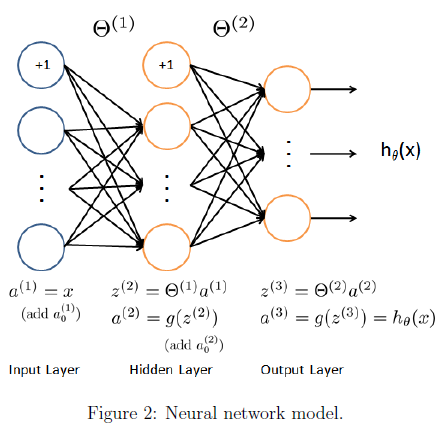

    You have been provided with a set of network parameters $(\Theta^{(1)},\Theta^{(2)})$ already trained by us. These are stored in `ex3weights.mat` and are loaded into `Theta1` and `Theta2 `by running the code below. The parameters have dimensions that are sized for a neural network with 25 units in the second layer and 10 output units (corresponding to the 10 digit classes).

load('ex3data1.mat');
m = size(X, 1);

% Randomly select 100 data points to display
sel = randperm(size(X, 1));
sel = sel(1:100);
displayData(X(sel, :));

% Load saved matrices from file
load('ex3weights.mat'); 
% Theta1 has size 25 x 401
% Theta2 has size 10 x 26

### 2.2 Feedforward propagation and prediction

Now you will implement feedforward propagation for the neural network. You will need to complete the code in `predict.m` to return the neural network's prediction. You should implement the feedforward computation that computes $h_\theta(x^{(i)})$ for every example $i$ and returns the associated predictions. Similar to the one-vs-all classication strategy, the prediction from the neural network will be the label that has the largest output $(h_\theta(x))_k$.

**Implementation Note: **The matrix `X` contains the examples in rows. When you complete the code in `predict.m`, you will need to add the column of 1's to the matrix. The matrices `Theta1` and `Theta2` contain the parameters for each unit in rows. Specically, the first row of `Theta1` corresponds to the first hidden unit in the second layer. In MATLAB, when you compute $z^{(2)} = \Theta^{(1)}a^{(1)}$, be sure that you index (and if necessary, transpose) `X` correctly so that you get $a^{(1)}$ as a column vector.

Once you are done, run the code below to call your predict function using the loaded set of parameters for `Theta1` and `Theta2`. You should see that the accuracy is about 97.5%.

pred = predict(Theta1, Theta2, X);
fprintf('\nTraining Set Accuracy: %f\n', mean(double(pred == y)) * 100);

The code below will displaying images from the training set one at a time, while the console prints out the predicted label for the displayed image. Rerun to repeat with another image.

%  Randomly permute examples
rp = randi(m);
% Predict
pred = predict(Theta1, Theta2, X(rp,:));
fprintf('\nNeural Network Prediction: %d (digit %d)\n', pred, mod(pred, 10));
% Display 
displayData(X(rp, :));   

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

## Submission and Grading

After completing this assignment, be sure to use the submit function to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored.

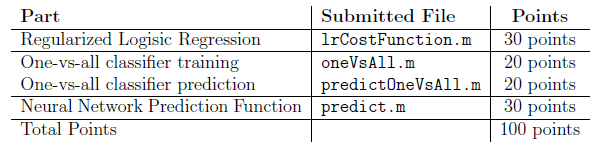

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.